# Time-Frequency Convolutional Neural Network for EEG Data Classification

This example shows how to classify electroencephalographic (EEG) time series from persons with and without epilepsy using a time-frequency convolutional network. The convolutional network predicts the class of the EEG data based on the continuous wavelet transform (CWT). The example compares the time-frequency network against a 1-D convolutional network. Unlike deep learning networks that use the magnitude or squared magnitude of the CWT (scalogram) as a preprocessing step, this example uses a differentiable scalogram layer. With a differentiable scalogram layer inside the network, you can put learnable operations before and after the scalogram. Layers of this type significantly expand the architectural variations that are possible with time-frequency transforms.

## Data -- Description, Attribution, and Download Instructions

The data used in this example is the Bonn EEG Data Set. The data is currently available at [EEG Data Download](https://www.ukbonn.de/en/epileptology/workgroups/lehnertz-workgroup-neurophysics/downloads/) and [The Bonn EEG time series download page](https://www.upf.edu/web/ntsa/downloads/-/asset_publisher/xvT6E4pczrBw/content/2001-indications-of-nonlinear-deterministic-and-finite-dimensional-structures-in-time-series-of-brain-electrical-activity-dependence-on-recording-regi?inheritRedirect=false&redirect=https://www.upf.edu/web/ntsa/downloads?p_p_id%3D101_INSTANCE_xvT6E4pczrBw%26p_p_lifecycle%3D0%26p_p_state%3Dnormal%26p_p_mode%3Dview%26p_p_col_id%3Dcolumn-1%26p_p_col_count%3D1#.X5Ep-S337UI). See [The Bonn EEG time series download page](https://www.upf.edu/web/ntsa/downloads/-/asset_publisher/xvT6E4pczrBw/content/2001-indications-of-nonlinear-deterministic-and-finite-dimensional-structures-in-time-series-of-brain-electrical-activity-dependence-on-recording-regi?inheritRedirect=false&redirect=https://www.upf.edu/web/ntsa/downloads?p_p_id%3D101_INSTANCE_xvT6E4pczrBw%26p_p_lifecycle%3D0%26p_p_state%3Dnormal%26p_p_mode%3Dview%26p_p_col_id%3Dcolumn-1%26p_p_col_count%3D1#.X5Ep-S337UI) for legal conditions on the use of the data. The authors have kindly permitted the use of the data in this example.

The data in this example were first analyzed and reported in:

[Andrzejak, Ralph G., Klaus Lehnertz, Florian Mormann, Christoph Rieke, Peter David, and Christian E. Elger. “Indications of Nonlinear Deterministic and Finite-Dimensional Structures in Time Series of Brain Electrical Activity: Dependence on Recording Region and Brain State.” Physical Review E 64, no. 6 (2001). https://doi.org/10.1103/physreve.64.061907](https://journals.aps.org/pre/abstract/10.1103/PhysRevE.64.061907)

The data consists of five sets of 100 single-channel EEG recordings. The resulting single-channel EEG recordings were selected from 128-channel EEG recordings after visually inspecting each channel for obvious artifacts and satisfying a weak stationarity criterion. See the linked paper for details.

The original paper 

- designates the class names for these five sets as A-E. Each 

- recording is 23.6 seconds in duration sampled at 173.61 Hz, and 

- each time series contains 4097 samples. 

The conditions are as follows:

- A — Normal subjects with eyes open

- B — Normal subjects with eyes closed

- C — Seizure-free recordings from patients with epilepsy. Recordings obtained from hippocampus in the hemisphere opposite the epileptogenic zone

- D — Seizure-free recordings from patients with epilepsy. Recordings obtained from epileptogenic zone.

- E — Recordings from patients with epilepsy showing seizure activity.

The zip files corresponding to this data are labeled as z.zip (A), o.zip (B), n.zip (C), f.zip (D), and s.zip (E).

The example assumes you have downloaded and unzipped the zip files into folders named `Z`, `O`, `N`, `F`, and `S` respectively. The following code assumes that all the .zip files have been downloaded into `BonnEEG `under the current directory.

clear; 
dataDir = fullfile(pwd,"BonnEEG");
cd("BonnEEG");
unzip("z.zip",dataDir)
unzip("o.zip",dataDir)
unzip("n.zip",dataDir)
unzip("f.zip",dataDir)
unzip("s.zip",dataDir)
cd("..")

## Prepare Data for Training

The individual EEG time series are stored as .txt files in each of the `Z`, `N`, `O`, `F`, and `S` folders under `dataDir`. Use a `tabularTextDatastore` to read the data. Create a tabular text datastore and create a categorical array of signal labels based on the folder names.

tds = tabularTextDatastore(dataDir,"IncludeSubfolders",true,"FileExtensions",".txt");

The zip files were created on the macOS. The unzip function often creates a folder called `_MACOSX`. If this folder appears in `dataDir`, delete it.

extraTXT = contains(tds.Files,"__MACOSX");
tds.Files(extraTXT) = [];

Create labels for the data based on the first letter of the text file name.

labels = filenames2labels(tds.Files,"ExtractBetween",[1 1]);

Use the read object function to create a table containing the data. Reshape the signals as a cell array of row vectors so they conform with the deep learning networks used in the example.

ind = 1;
eegData = cell(numel(labels),1);
while hasdata(tds)
    tsTable = read(tds);
    ts = tsTable.Var1;
    eegData{ind} = reshape(ts,1,[]);  
    ind = ind+1;
end

Plot a sample EEG data.

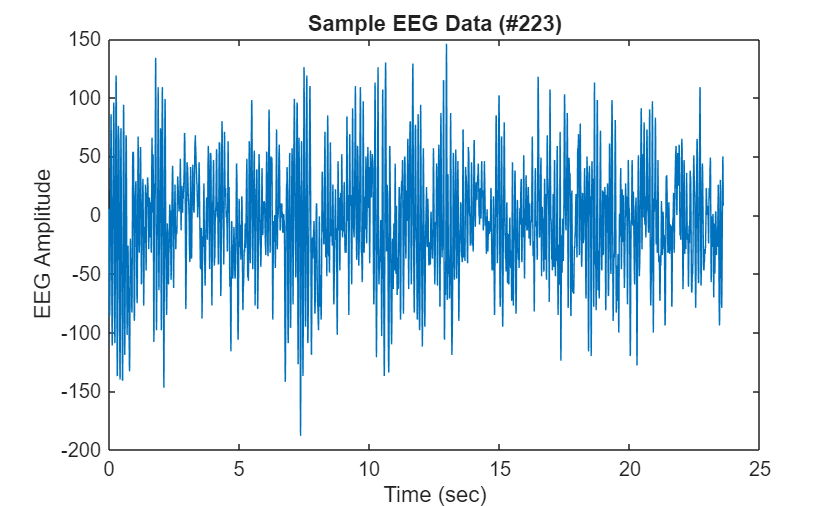

n =223;
T=23.6; fs=173.61; t = 0:1/fs:T-1/fs;
plot(t, eegData{n})
xlabel("Time (sec)")
ylabel("EEG Amplitude")
title("Sample EEG Data (#"+n+")")

Given the five conditions present in the data, there are multiple meaningful and clinically informative ways to partition the data. One relevant way is to group the `Z` and `O` labels (non-epileptic subjects with eyes open and closed) as "Normal". Similarly, the two conditions recorded in epileptic subjects without overt seizure activity (`F` and `N`) may be grouped as "Seizure-Free". Finally, we designate the recordings obtained in epileptic subjects with seizure activity as "Seizure".

labels3Class = labels;
labels3Class = removecats(labels3Class,["F","N","O","S","Z"]);
labels3Class(labels == categorical("Z") | labels == categorical("O")) = categorical("Normal");
labels3Class(labels == categorical("F") | labels == categorical("N")) = categorical("Seizure-Free");
labels3Class(labels == categorical("S")) = categorical("Seizure");

Display the number of recordings in each of our derived categories. The summary shows three imbalanced classes with 100 recordings in the "Seizure" category and 200 recordings in each of the "Seizure-Free" and "Normal" categories.

T0 = countlabels(labels3Class);
disp(T0)

       Label        Count    Percent
    ____________    _____    _______

    Normal           200       40   
    Seizure-Free     200       40   
    Seizure          100       20   



Partition the data into a training set, a test set, and a validation set consisting of 70%, 20%, and 10% of the recordings, respectively.

idxSPN = splitlabels(labels3Class,[0.7 0.2 0.1]);

trainDataSPN = eegData(idxSPN{1});
trainLabelsSPN = labels3Class(idxSPN{1});
testDataSPN = eegData(idxSPN{2});
testLabelsSPN = labels3Class(idxSPN{2});
validationDataSPN = eegData(idxSPN{3});
validationLabelsSPN = labels3Class(idxSPN{3});

Examine the proportion of each condition across the three sets.

Table = Table_Summary(labels3Class, trainLabelsSPN, validationLabelsSPN, testLabelsSPN)

Table = 4×5 table
       Classes        Training    Validation    Test    Total
    ______________    ________    __________    ____    _____

    "Normal"            140           20         40      200 
    "Seizure-Free"      140           20         40      200 
    "Seizure"            70           10         20      100 
    "Total"             350           50        100      500 


Because of the class imbalance, create weights proportional to the inverse class frequencies to use in training the deep learning model. This mitigates the tendency of the model to become biased toward more prevalent classes.

classwghts = numel(labels3Class)./(3*countcats(labels3Class));

Plot a sample EEG data from each class.

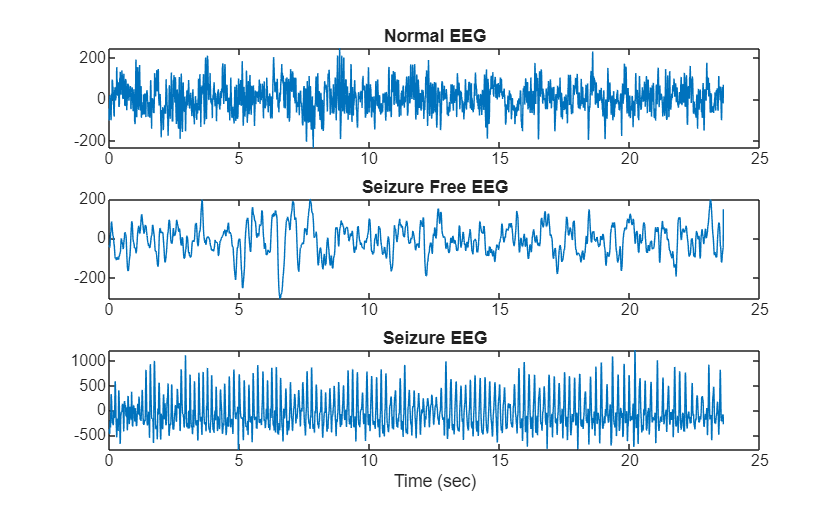

N = find(labels3Class=="Normal"); i_N = N(randi(length(N),1));
F = find(labels3Class=="Seizure-Free"); i_F = F(randi(length(F),1));
S = find(labels3Class=="Seizure"); i_S = S(randi(length(S),1));
figure
subplot(311); plot(t, eegData{i_N}); title("Normal EEG")
subplot(312); plot(t, eegData{i_F}); title("Seizure Free EEG")
subplot(313); plot(t, eegData{i_S}); title("Seizure EEG")
xlabel("Time (sec)")

## 1-D Convolutional Neural Network

For reference, we compare the performance of the time-frequency deep learning network with a 1-D convolutional network which uses the raw time series as inputs. To the extent possible, the layers between the time-frequency network and time-domain network are kept equivalent. Note there are many variations of deep learning networks which can operate on the raw time series data. The inclusion of this particular network is presented as a point of reference and not intended as a rigorous comparison of time series network performance with that of the time-frequency network.

netconvSPN = [sequenceInputLayer(1,"MinLength",4097,"Name","input","Normalization","zscore")
    convolution1dLayer(5,1,"stride",2)
    maxPooling1dLayer(10)
    batchNormalizationLayer
    reluLayer
    convolution1dLayer(5,5,"Padding","same")
    batchNormalizationLayer
    reluLayer
    convolution1dLayer(5,10,"Padding","same")
    maxPooling1dLayer(4)
    batchNormalizationLayer
    reluLayer
    globalAveragePooling1dLayer
    dropoutLayer(0.4)
    fullyConnectedLayer(3)
    softmaxLayer
    ];

lossFcn = @(Y,T)crossentropy(Y,T,classwghts,...
    NormalizationFactor="all-elements", ...
    WeightsFormat="C"); %#ok

options = trainingOptions("adam", ...
    "MaxEpochs",40, ...
    "MiniBatchSize",20, ...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",{validationDataSPN,validationLabelsSPN},...
    "L2Regularization",1e-2,...
    "OutputNetwork","best-validation-loss",...
    "Verbose", false, ...
    "Metrics","accuracy"); %#ok

You can view the layers of the network:

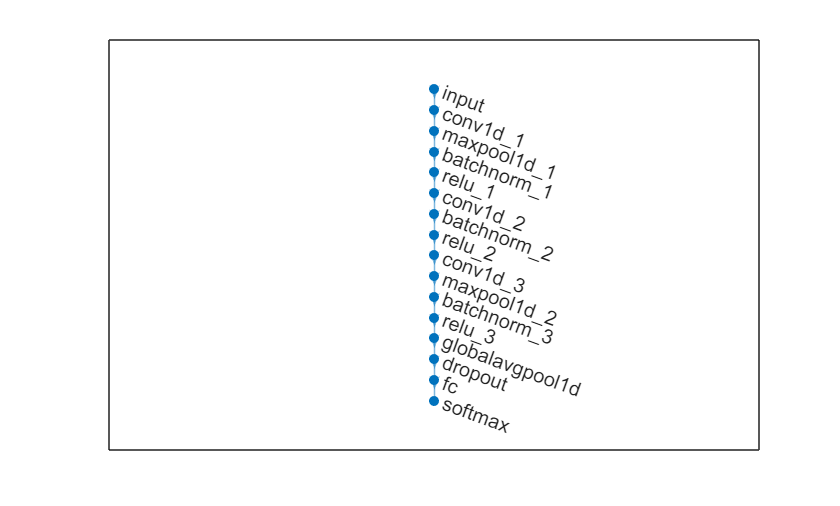

figure
plot((dlnetwork(netconvSPN)))

You can view the network in [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) app.

deepNetworkDesigner(netconvSPN)

Train the network using the [trainNetwork](docid:nnet_ref#bu6sn4c) function or load it if it was previously trained. The training shows good agreement between the training and validation data sets. Specify the network training options. Output the network with the best validation loss.


if false % train the network
    trainedNetConvSPN = trainnet(trainDataSPN,trainLabelsSPN,netconvSPN,lossFcn,options); %#ok
    save("trainedNetConvSPN.mat", "trainedNetConvSPN")         % Save the trained model to be loaded later
else                                
    load trainedNetConvSPN;         % Load the pretrained model 
end

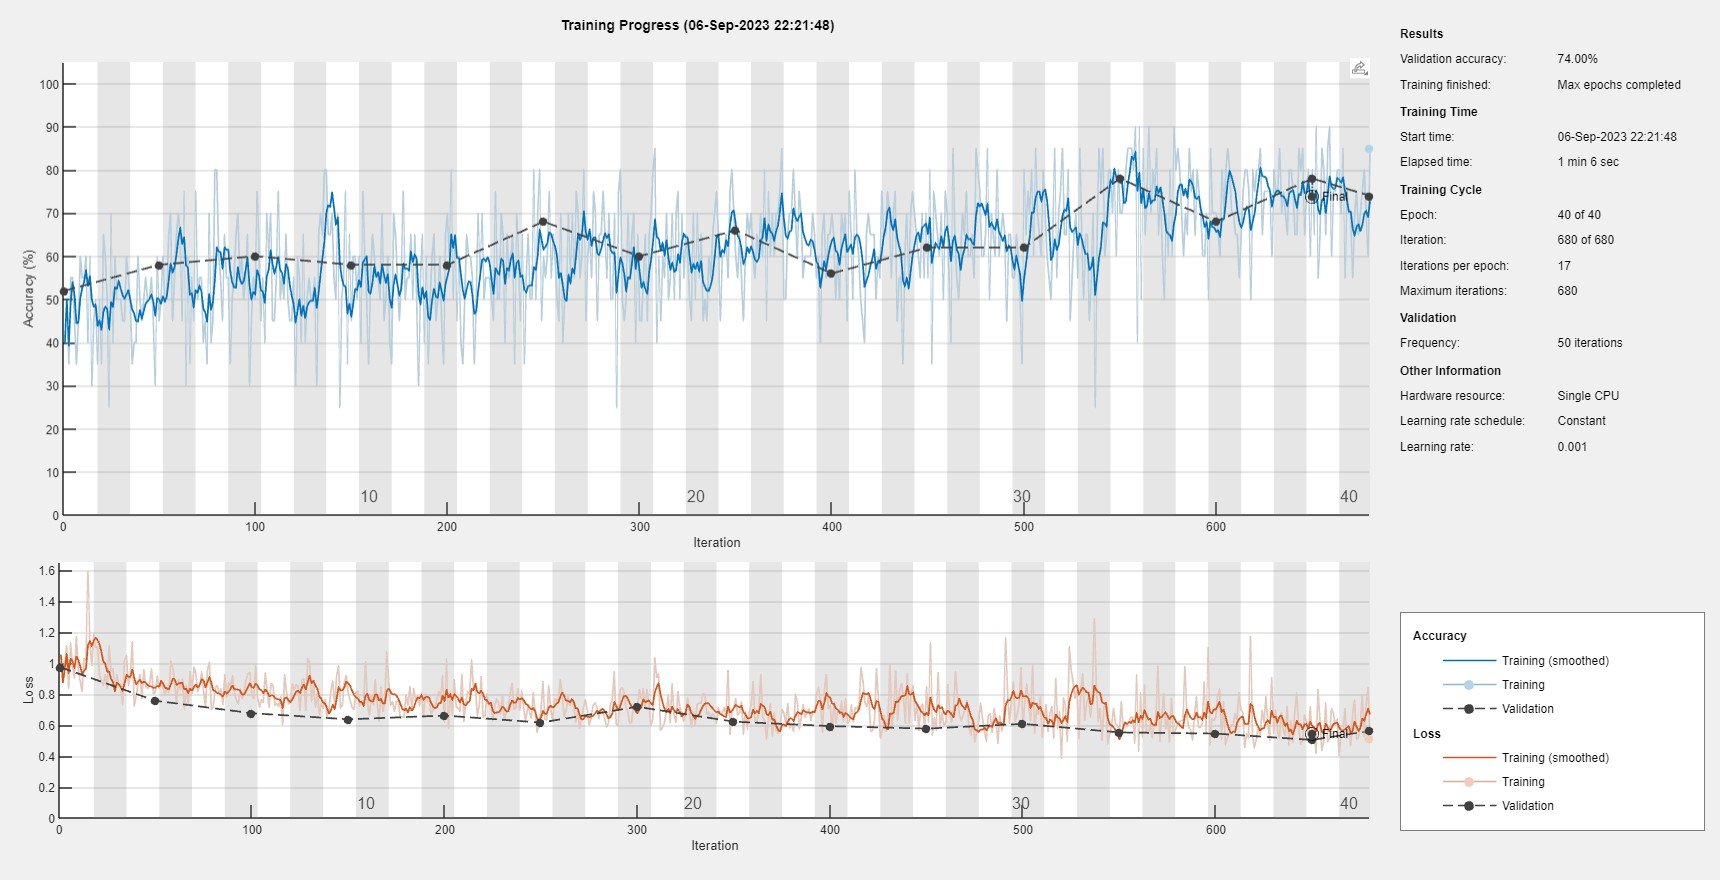

The training shows good agreement between accuracy on the training set and the validation set. However, the network accuracy during training is relatively poor. After training completes, test our model on the held-out test set. Plot the confusion chart and examine the model"s recall and precision.

ypredconvSPN = trainedNetConvSPN.classify(testDataSPN);
sum(ypredconvSPN == testLabelsSPN)/numel(testLabelsSPN)

ans = 0.6600

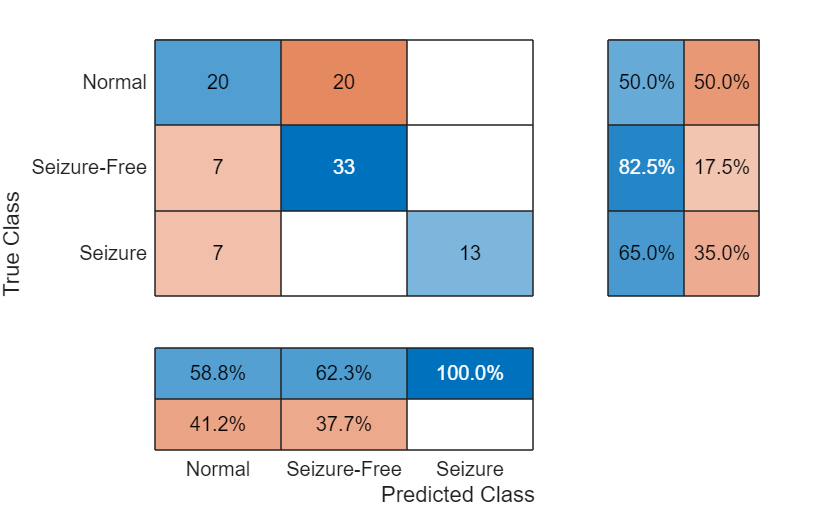

hf = figure;
confusionchart(hf,testLabelsSPN,ypredconvSPN,"RowSummary","row-normalized","ColumnSummary","column-normalized")

The recall and precision performance of the network is not surprisingly substantially less accurate than the time-frequency network.

## Time-Frequency Deep Learning Network

Prior to training our time-frequency model, inspect the time series data and scalograms for a random example from each class. The plotting is done by the helper function, `helperExamplePlot`.

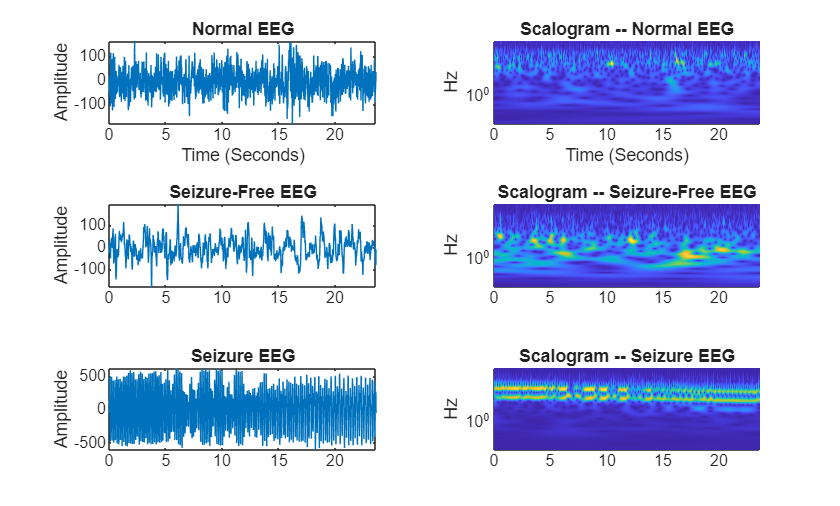

 

helperExamplePlot(t, fs, trainDataSPN,trainLabelsSPN)

The scalogram is an ideal time-frequency transformation for time series data like EEG waveforms, which feature both slowly-oscillating and transient phenomena.

Define a network that uses a time-frequency transformation of the input signal for classification.

netSPN = [
    sequenceInputLayer(1,"MinLength",4097,"Name","input","Normalization","zscore")
    convolution1dLayer(5,1,"stride",2)
    cwtLayer("SignalLength",2047,"IncludeLowpass",true,"Wavelet","amor")
    maxPooling2dLayer([5,10])
    convolution2dLayer([5,10],5,"Padding","same")
    maxPooling2dLayer([5,10])  
    batchNormalizationLayer
    reluLayer
    convolution2dLayer([5,10],10,"Padding","same")
    maxPooling2dLayer([2,4])   
    batchNormalizationLayer
    reluLayer
    flattenLayer
    globalAveragePooling1dLayer
    dropoutLayer(0.4)
    fullyConnectedLayer(3)
    softmaxLayer
    ];

lossFcn = @(Y,T)crossentropy(Y,T,classwghts,...
    NormalizationFactor="all-elements", ...
    WeightsFormat="C"); 

options = trainingOptions("adam", ...
    "MaxEpochs",40, ...
    "MiniBatchSize",20, ...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",{validationDataSPN,validationLabelsSPN},...
    "L2Regularization",1e-2,...
    "OutputNetwork","best-validation-loss",...
    "Verbose", false, ...
    "Metrics","accuracy");

The network features an input layer, which normalizes the signals to have zero mean and unit standard deviation.  Unlike  [1], no preprocessing bandpass filter is used in this network. Rather, a learnable 1-D convolutional layer is used prior to obtaining the scalogram. We use a stride of 2 in the 1-D convolutional layer to downsample the size of the data along the time dimension. This reduces the computational complexity of the following scalogram. The next layer, [cwtLayer](docid:wavelet_ref#mw_fb6e2e30-89ee-423f-996a-c7546c1edb73), obtains the scalogram (magnitude CWT) of the input signal. For each input signal, the output of the CWT layer is a sequence of time-frequency maps. This layer is configurable. In this case, we use the analytic Morlet wavelet and include the lowpass scaling coefficients.  See [3] for another scalogram-based analysis of this data, and [2] for another wavelet-based analysis using the tunable Q-factor wavelet transform.

Subsequent to obtaining the scalogram, the network operates along both the time and frequency dimensions of the scalogram with 2-D operations until the `flattenLayer`. After `flattenLayer`, the model averages the output along the time dimension and uses a dropout layer to help prevent overfitting. The fully connected layer reduces the output along the channel dimension to equal the number of data classes (3).

You can view the network in [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html) app.

% deepNetworkDesigner(netSPN)

Train the network using the [trainNetwork](docid:nnet_ref#bu6sn4c) function or load it if it was previously trained. The training shows good agreement between the training and validation data sets. 

if false % train the network
    trainedNetSPN = trainnet(trainDataSPN,trainLabelsSPN,netSPN,lossFcn,options); %#ok
    save("trainedNetSPN.mat", "trainedNetSPN") ;         % Save the trained model to be loaded later
else                            % Load the pretrained model 
    load trainedNetSPN;    
end

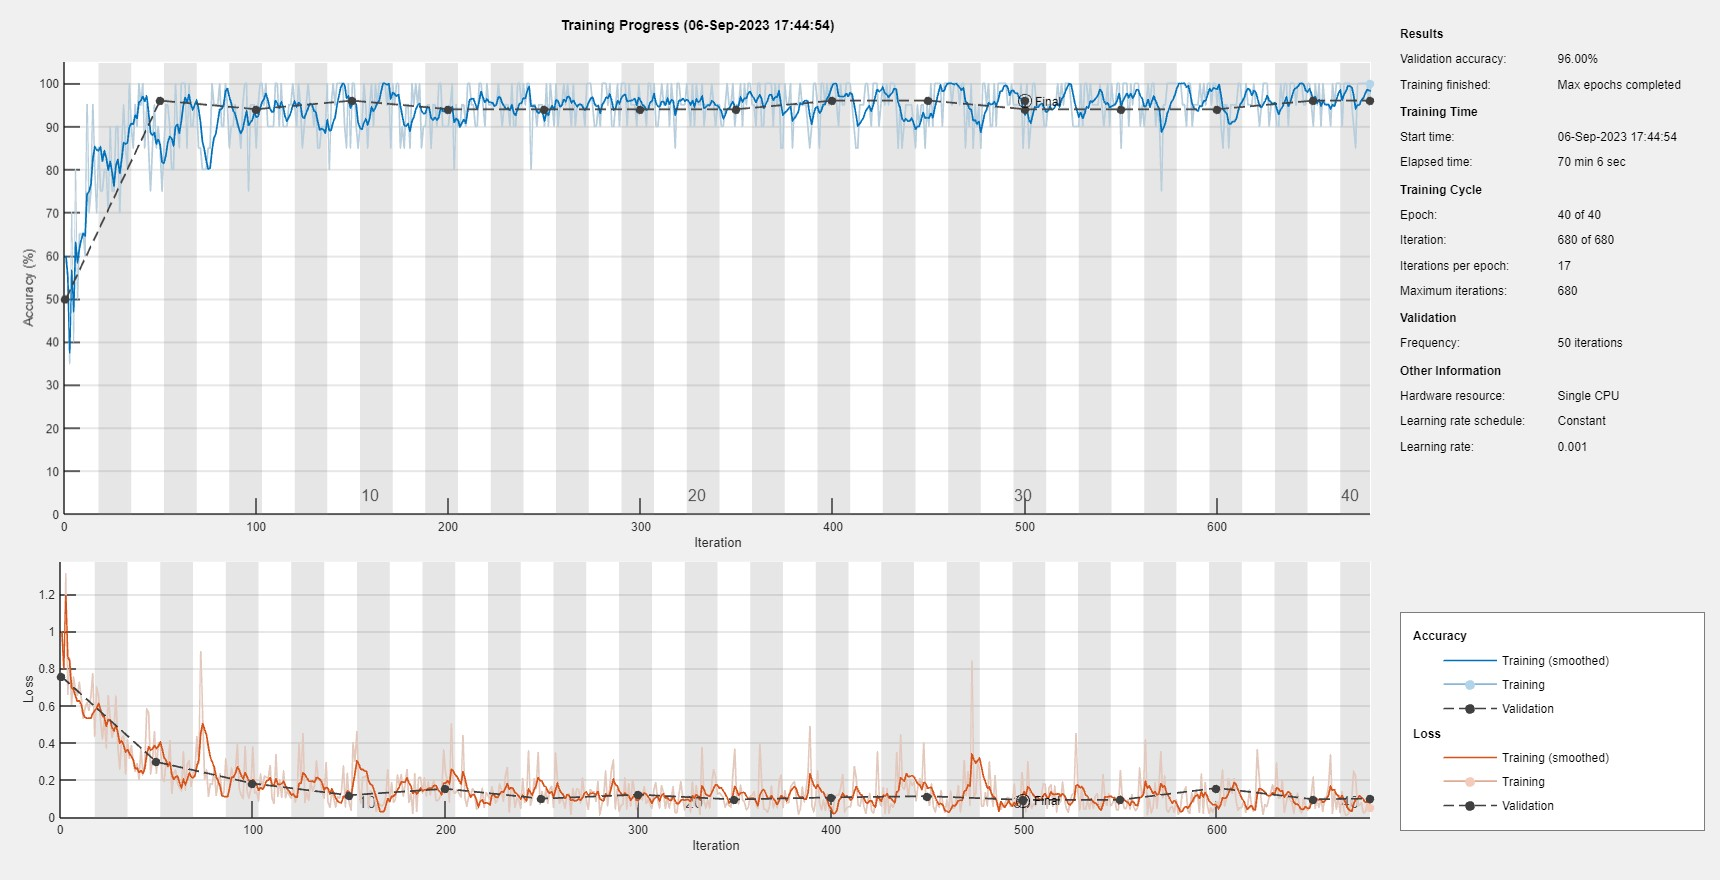

After training completes, test the network on the held-out test set. Plot the confusion chart and examine the network's recall and precision.

ypredSPN = trainedNetSPN.classify(testDataSPN);
sum(ypredSPN == testLabelsSPN)/numel(testLabelsSPN)

ans = 0.9800

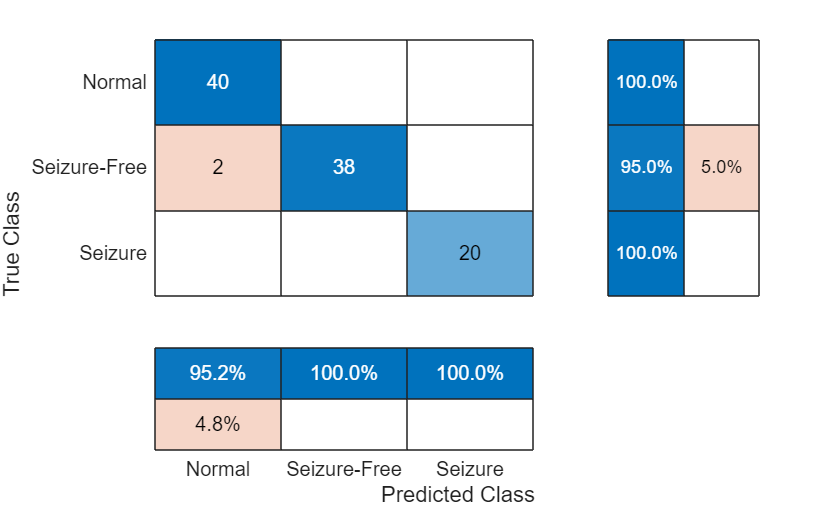

hf = figure;
confusionchart(hf,testLabelsSPN,ypredSPN,"RowSummary","row-normalized","ColumnSummary","column-normalized")

The confusion chart shows good performance on the test set. The row summaries in the confusion chart show the model's *recall*, while the column summaries show the *precision*. Both recall and precision generally fall between 95 and 100 percent. Performance was generally better for the "Seizure" and "Normal" classes than the "Seizure-Free" class.

## Summary

In this example, a time-frequency convolutional network was used to classify EEG recordings in persons with and without epilepsy. A crucial difference between this example and the scalogram network used in [3], was the use of a differentiable scalogram inside the deep learning model. This flexibility enables us to combine 1-D and 2-D deep learning layers in the same model, as well as place learnable operations before the time-frequency transform. The approach was compared against analogous 1-D convolutional networks. The 1-D convolutional networks were constructed to be as close to the time-frequency model as possible. It is likely that more optimal 1-D convolutional or recurrent networks can be designed for this data. As previously mentioned, the focus of the example was to construct a differentiable time-frequency network for real-world EEG data, not to conduct an in-depth comparison of the time-frequency model against competing time series models.

## References

[1] Andrzejak, Ralph G., Klaus Lehnertz, Florian Mormann, Christoph Rieke, Peter David, and Christian E. Elger. “Indications of Nonlinear Deterministic and Finite-Dimensional Structures in Time Series of Brain Electrical Activity: Dependence on Recording Region and Brain State.” Physical Review E 64, no. 6 (2001). https://doi.org/10.1103/physreve.64.061907. 

[2] Bhattacharyya, Abhijit, Ram Pachori, Abhay Upadhyay, and U. Acharya. “Tunable-Q Wavelet Transform Based Multiscale Entropy Measure for Automated Classification of Epileptic EEG Signals.” Applied Sciences 7, no. 4 (2017): 385. https://doi.org/10.3390/app7040385. 

[3] Türk, Ömer, and Mehmet Siraç Özerdem. “Epilepsy Detection by Using Scalogram Based Convolutional Neural Network from EEG Signals.” Brain Sciences 9, no. 5 (2019): 115. https://doi.org/10.3390/brainsci9050115. 

*Copyright 2023 The MathWorks, Inc.*

function helperExamplePlot(t, Fs, trainDataSPN,trainLabelsSPN)

    ind = find(trainLabelsSPN == categorical("Seizure"));
    szidx = ind(randi(length(ind)));
    ind = find(trainLabelsSPN == categorical("Seizure-Free"));
    psidx = ind(randi(length(ind)));
    ind = find(trainLabelsSPN == categorical("Normal"));
    nidx = ind(randi(length(ind)));

    [scSZ,f] = cwt(trainDataSPN{szidx},Fs,"amor");
    scSZ = abs(scSZ);
    scPS = abs(cwt(trainDataSPN{psidx},Fs,"amor"));
    scN = abs(cwt(trainDataSPN{nidx},Fs,"amor"));
    tiledlayout(3,2)

    nexttile
    plot(t,trainDataSPN{nidx}), axis tight
    title("Normal EEG")
    ylabel("Amplitude")
    xlabel("Time (Seconds)")
    nexttile
    surf(t,f,scN), shading interp, view(0,90)
    set(gca,"Yscale","log"),axis tight
    title("Scalogram -- Normal EEG")
    ylabel("Hz")
    xlabel("Time (Seconds)")

    nexttile
    plot(t,trainDataSPN{psidx}),axis tight
    title("Seizure-Free EEG")
    ylabel("Amplitude")
    nexttile
    surf(t,f,scPS), shading interp, view(0,90)
    set(gca,"Yscale","log"),axis tight
    title("Scalogram -- Seizure-Free EEG")
    ylabel("Hz")

    nexttile
    plot(t,trainDataSPN{szidx}), axis tight
    title("Seizure EEG")
    ylabel("Amplitude")
    nexttile
    surf(t,f,scSZ), shading interp, view(0,90)
    set(gca,"Yscale","log"), axis tight
    title("Scalogram -- Seizure EEG")
    ylabel("Hz")   
end

function Table = Table_Summary(labels3Class, trainLabelsSPN, validationLabelsSPN, testLabelsSPN)
    T0 = countlabels(labels3Class);
    T1 = countlabels(trainLabelsSPN); 
    T2 = countlabels(validationLabelsSPN); 
    T3 = countlabels(testLabelsSPN);
    Table = table;
    Table.Classes = [[string(unique(labels3Class))];"Total"]; 
    Table.Training = [T1{:,2};sum(T1{:,2})]; 
    Table.Validation = [T2{:,2};sum(T2{:,2})]; 
    Table.Test = [T3{:,2};sum(T3{:,2})]; 
    Table.Total = [T0{:,2};sum(T0{:,2})];
end